clear all
fileName = 'fyy1.xlsx';
sheetName='Sheet2';
data_all = readtable(fileName, 'Sheet', sheetName);

varNames = data_all.Properties.VariableNames;


car_diesel=data_all(strcmp(data_all.BodyType,'Cars')...
    &strcmp(data_all.Fuel,'Diesel'),4:end-2);
car_petrol=data_all(strcmp(data_all.BodyType,'Cars')...
    &strcmp(data_all.Fuel,'Petrol'),4:end-2);
% car_BE=data_all(strcmp(data_all.BodyType,'Cars')...
%     &strcmp(data_all.Fuel,'Battery electric'),4:end-2);

LGV_diesel=data_all(strcmp(data_all.BodyType,'Light goods vehicles')...
    &strcmp(data_all.Fuel,'Diesel'),4:end-2);
LGV_petrol=data_all(strcmp(data_all.BodyType,'Light goods vehicles')...
    &strcmp(data_all.Fuel,'Petrol'),4:end-2);
% LGV_BE=data_all(strcmp(data_all.BodyType,'Light goods vehicles')...
%     &strcmp(data_all.Fuel,'Battery electric'),4:end-2);


bus_total=data_all(strcmp(data_all.BodyType,'Buses and coaches')...
    &strcmp(data_all.Fuel,'Total'),4:end-2);

HGV_total=data_all(strcmp(data_all.BodyType,'Heavy goods vehicles')...
    &strcmp(data_all.Fuel,'Total'),4:end-2);

motor_total=data_all(strcmp(data_all.BodyType,'Motorcycles')...
    &strcmp(data_all.Fuel,'Total'),4:end-2);

% Calculate the survival rate matric of each type
[car_diesel_remain_number_year,car_diesel_remain_rate_age]=get_survival_rate_matridatac(car_diesel);
[car_petrol_remain_number_year,car_petrol_remain_rate_age]=get_survival_rate_matridatac(car_petrol);

[LGV_diesel_remain_number_year,LGV_diesel_remain_rate_age]=get_survival_rate_matridatac(LGV_diesel);
[LGV_petrol_remain_number_year,LGV_petrol_remain_rate_age]=get_survival_rate_matridatac(LGV_petrol);

[bus_remain_number_year,bus_remain_rate_age]=get_survival_rate_matridatac(bus_total);
[HGV_remain_number_year,HGV_remain_rate_age]=get_survival_rate_matridatac(HGV_total);
[motor_remain_number_year,motor_remain_rate_age]=get_survival_rate_matridatac(motor_total);

All_remain_number_year_data=cat(3,car_diesel_remain_number_year,LGV_diesel_remain_number_year,bus_remain_number_year,HGV_remain_number_year,...
    car_petrol_remain_number_year,LGV_petrol_remain_number_year,motor_remain_number_year);
All_remain_rate_age_data=cat(3,car_diesel_remain_rate_age,LGV_diesel_remain_rate_age,bus_remain_rate_age,HGV_remain_rate_age,...
    car_petrol_remain_rate_age,LGV_petrol_remain_rate_age,motor_remain_rate_age);
TitleNameSet={'Diesel Car','Diesel LGV','Bus','HGV','Petrol Car','Petrol LGV','Motor'};

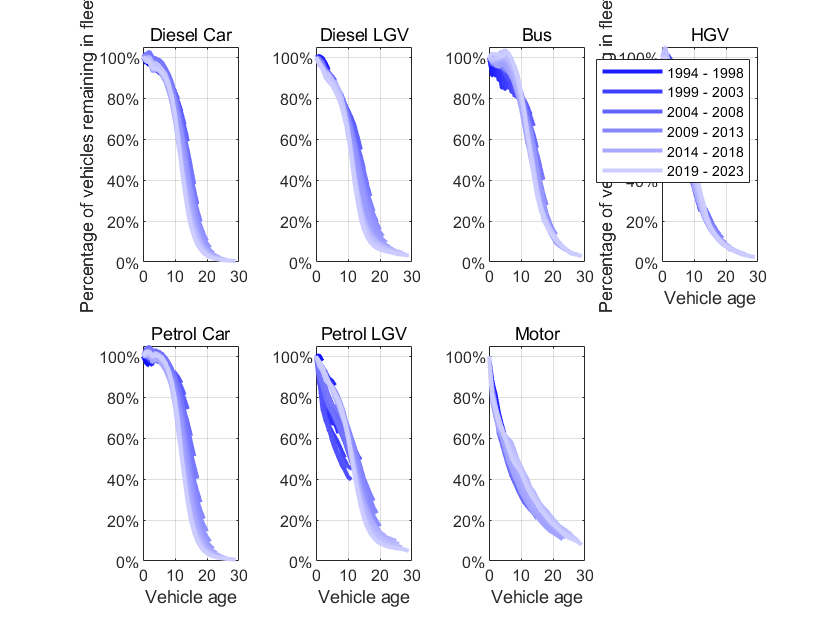

% Draw the survival rate line
global cmap
years_num=30;
cmap = [linspace(0, 0.8, years_num)', linspace(0, 0.8, years_num)', ones(years_num, 1)]; % 蓝色渐变

figure(1)
legend_flag=0;
for sheet=1:7
    subplot(2, 4, sheet)
    sheet_data=All_remain_rate_age_data(:,:,sheet);
if sheet==4
    legend_flag=1;
end
    legend_flag=draw_rate_age(sheet_data,legend_flag);



    if sheet>3
        xlabel('Vehicle age');
    end
    if sheet==1||sheet==4
        ylabel('Percentage of vehicles remaining in fleet');
    end
    yticks(0:0.2:1); % 设置纵坐标刻度
    yticklabels(arrayfun(@(v) [num2str(v*100), '%'], 0:0.2:1, 'UniformOutput', false)); % 格式化为百分比
    ylim([0, 1.05]);
    xlim([0,years_num])
    
    grid on;

    title(TitleNameSet{1, sheet})

end
hold off

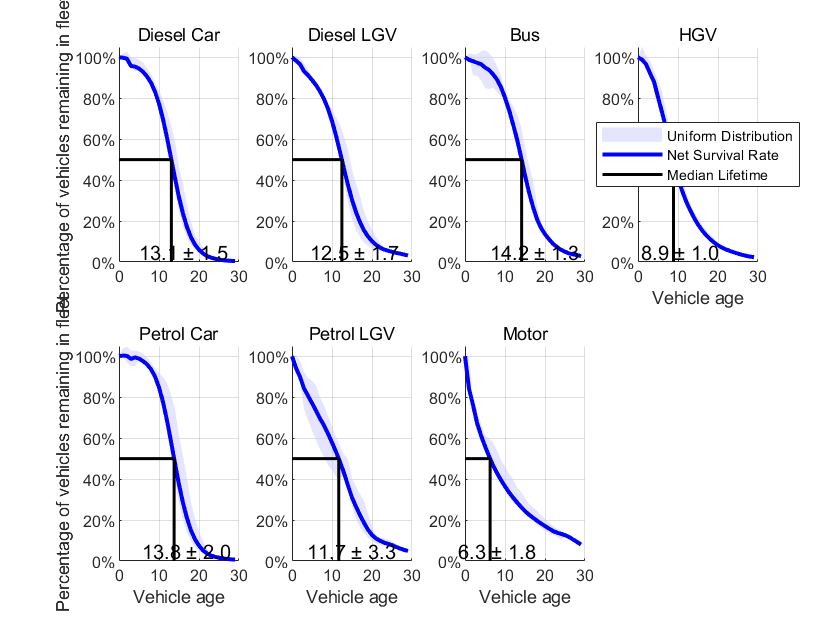

figure(2)
mid_survival_rate=zeros(years_num,7);
for sheet=1:7
    
    sheet_data=All_remain_rate_age_data(:,:,sheet);
    % Step 2: 计算每个年龄的上下界
    upperBound = nanmax(sheet_data, [], 2);  % 每行最大值
    lowerBound = nanmin(sheet_data, [], 2);  % 每行最小值
%     meanValue=nanmean(sheet_data, 2);   
    meanValue = weighted_matrix_mean(sheet_data);
    smoothedRates = smooth(meanValue, 0.1, 'loess'); % 使用局部加权回归平滑
    
    mid_survival_rate(:,sheet)=smoothedRates;

    %找到0.5 rate对应的年龄
    targetRate = 0.5;  % 目标生存率
    ages = 0:years_num-1;   % 对应的年龄范围

    % 找到 meanCurve 中等于或接近 targetRate 的年龄
    ageAtTargetRate = interp1(smoothedRates, ages, targetRate, 'linear', 'extrap');
    upperageAtTargetage=interp1(upperBound,ages, targetRate, 'linear', 'extrap');
    lowerageAtTargetage=interp1(lowerBound,ages, targetRate, 'linear', 'extrap');
    ageUncertainty=abs(upperageAtTargetage-lowerageAtTargetage)/2;


    % Step 4: 绘图
    subplot(2, 4, sheet)
    hold on;

    % 阴影部分：上下界区域
    fill([0:years_num-1, years_num:-1:1], [upperBound; flipud(lowerBound)], ...
        [0.8 0.8 1], 'EdgeColor', 'none', 'FaceAlpha', 0.5);

    % 平均值曲线
    plot(0:years_num-1, smoothedRates, 'b-', 'LineWidth', 2);

    % 标注目标点: 添加横线和竖线
    line([0, ageAtTargetRate], [targetRate, targetRate], 'Color', 'k', 'LineStyle', '-', 'LineWidth', 1.5); % 横线
    line([ageAtTargetRate, ageAtTargetRate], [0, targetRate], 'Color', 'k', 'LineStyle', '-', 'LineWidth', 1.5); % 竖线
    % 标注m目标点文本
    text(ageAtTargetRate -8, 0.05, ...
        sprintf('%.1f ± %.1f', ageAtTargetRate, ageUncertainty), ...
        'HorizontalAlignment', 'left', 'Color', 'black', 'FontSize', 10);

    % 图例和标签
    if sheet>3
        xlabel('Vehicle age');
    end
    if sheet==1||sheet==5
        ylabel('Percentage of vehicles remaining in fleet');
    end
    yticks(0:0.2:1); % 设置纵坐标刻度
    yticklabels(arrayfun(@(v) [num2str(v*100), '%'], 0:0.2:1, 'UniformOutput', false)); % 格式化为百分比
    ylim([0, 1.05]);
    xlim([0,years_num])
    grid on;


    title(TitleNameSet{1, sheet});
    if sheet==4
        legend({'Uniform Distribution', 'Net Survival Rate', 'Median Lifetime'}, 'Location', 'Best');
    end
    grid on;
    hold off;

end
hold off

 save('survival_number_and_rates.mat','All_remain_number_year_data',...
     'All_remain_rate_age_data','mid_survival_rate','TitleNameSet',"-mat");

function legend_flag=draw_rate_age(sheet_data,legend_flag)
global cmap
[~, cols] = size(sheet_data);

% 创建新图窗口

for col = 1:cols
    column_value=sheet_data(:,col);
    first_nan_idx=find(isnan(column_value), 1);

    if isempty(first_nan_idx)
        columnDataNonNaN=column_value;
    elseif first_nan_idx>1
        columnDataNonNaN=column_value(1:first_nan_idx-1);
    else
        columnDataNonNaN=0;
    end
    currentColor = cmap(col, :);
    if legend_flag==1
        handles(col) = plot(0:length(columnDataNonNaN)-1,columnDataNonNaN, 'Color', currentColor, 'LineWidth', 2);
        hold on;
        % 仅在特定索引处设置 legend 名称
        if ismember(col, [5, 10, 15, 20, 25, 30])
            set(handles(col), 'DisplayName', sprintf('%d - %d', 1994+col-5, 1994+col-1));

        else
            set(handles(col), 'HandleVisibility', 'off'); % 其他线条在 legend 中隐藏
        end

    else

        plot(0:length(columnDataNonNaN)-1,columnDataNonNaN, 'Color', currentColor,'LineWidth',2); % 每条线的颜色从深蓝到淡蓝
        hold on;
    end


end
if legend_flag==1
    legend show;
    legend('Location', 'northeast');
    legend_flag=0;
end

hold off
end


function pseudo_mean = weighted_matrix_mean(A)
    % 确定矩阵大小
    
alpha = 0.98;  % 递减因子
    [rows, cols] = size(A);
     

    % 预定义权重（假设权重适用于所有列）
    weights = cumprod([1, repmat(alpha, 1, cols)]);
    
%     % 取前 rows 个权重（防止 A 的行数大于权重长度）
%     weights = base_weights(1:min(rows, length(base_weights)))';
    
    % 预分配结果矩阵
    pseudo_mean = nan(rows, 1);
    
    % 遍历每一列
    for j = 1:rows
        % 取当前列数据
        raw_data = A(j, :);
        
        % 处理 NaN 值：找到非 NaN 元素
        valid_mask = ~isnan(raw_data);
        
        % 只对非 NaN 值进行加权
        valid_A = raw_data(valid_mask);
        valid_weights = weights(valid_mask);
        
        % 归一化权重
        valid_weights = valid_weights / sum(valid_weights);
        
        % 计算加权伪均值
        if ~isempty(valid_A)  % 确保至少有一个非 NaN 值
            pseudo_mean(j) = sum(valid_weights .* valid_A);
        else
            pseudo_mean(j) = NaN; % 若整列均为 NaN，则返回 NaN
        end
    end
end
